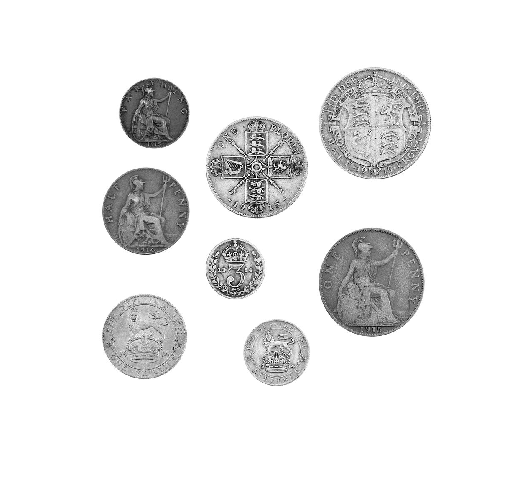

I = rgb2gray(imread('coins2.jpg'));
imshow(I);

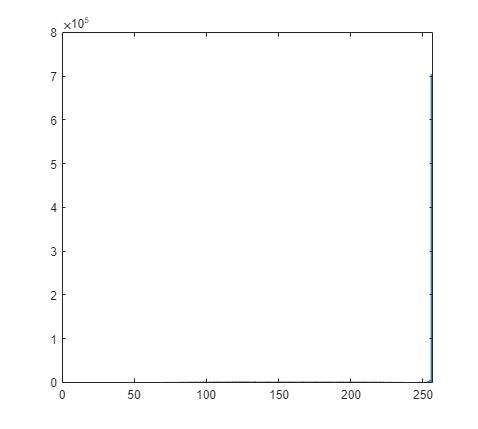

h = imhist(I);
bar(h)

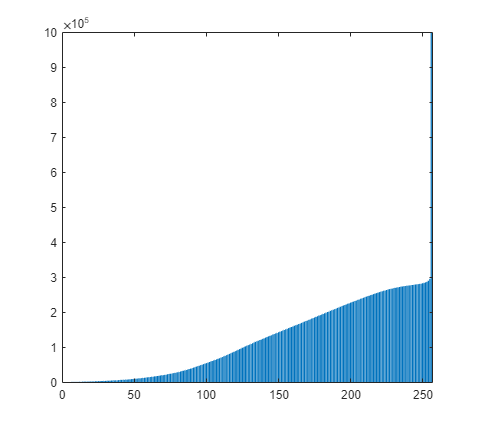

%% volem trobar un llindar tal que l'area sota la curva de abans del llindar sigui igual a un valor.
ha = cumsum(h);
bar(ha)

[f c]=size(I);
mida = f*c;
Area = 0.25*mida

Area = 250000

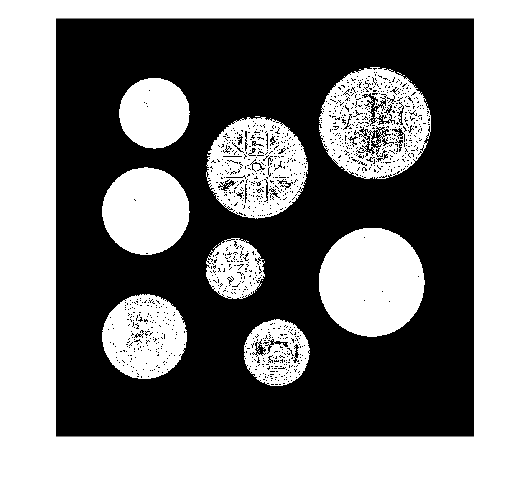

%Area = 8*pi*100*100;
r = ha > Area;
llindar = find(r,1);
BW = I < llindar;
imshow(BW);

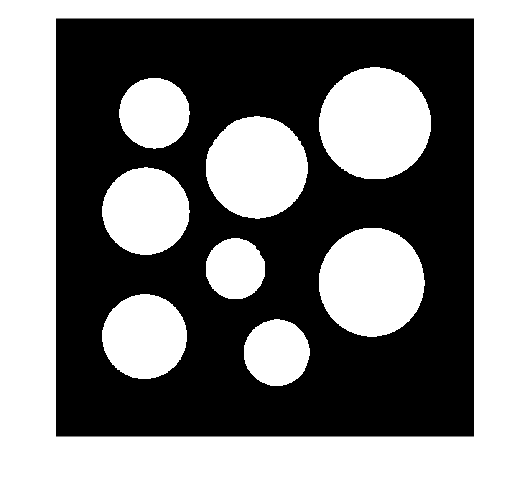

ee = strel('disk',5);
BWc = imclose(BW,ee);
imshow(BWc);

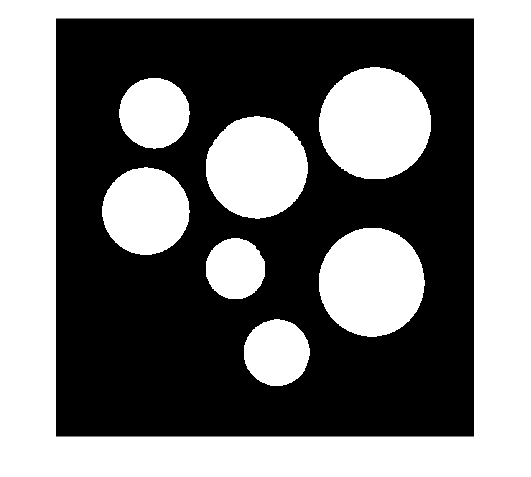

C = bwconncomp(BWc);
B = BWc;
%% borrem el primer element que trobem(escaneja columna per columna, de esquerra a dreta)
B(C.PixelIdxList{1})=0;
imshow(B);


npixels = cellfun(@numel,C.PixelIdxList);
[m,i] = max(npixels)

m = 56206

i = 8

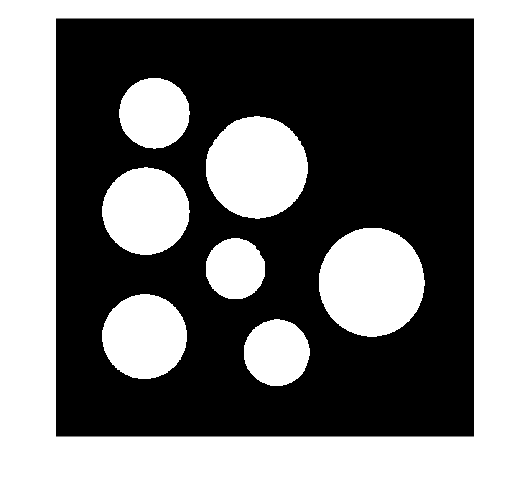


%%borrar la moneda mes gran
D = BWc;
D(C.PixelIdxList{i})=0;
imshow(D)


%%regionprops

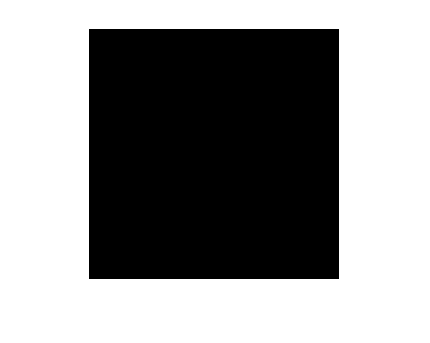

%%processat per blocs
%blkproc([4 4] pas , [50 50] pas + H*2)
J = blkproc(I,[4 4],[10 10],@bina,215);
imshow(J);

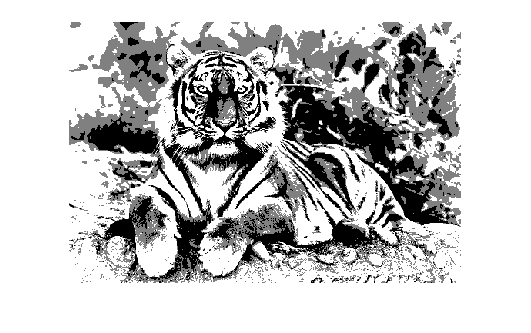

T = rgb2gray(imread('tiger2.jpg'));
Jt = blkproc(T,[1 1],[60 60],@bina,16);
imshow(Jt,[]);
saveas(gcf,'tigreton.png')